# Loading Data

clc;clear;
%Load SYrian Data
syrianDatasetExploration;

filePath = 'G:\.shortcut-targets-by-id\1YXV-SWkwjUwCHF0E-UodEuhZKomSyoO0\SU21_Collaboration\Full Gait Simscape\kinematic_data\Syrian_Dataset\File 01 Subjects information.xlsx'

sTemporalFile = 'G:\.shortcut-targets-by-id\1YXV-SWkwjUwCHF0E-UodEuhZKomSyoO0\SU21_Collaboration\Full Gait Simscape\kinematic_data\Syrian_Dataset\File 02 Spatio-temporal parameters.xlsx'

kinematicDataFile = 'C:\Users\nejac\Google Drive\SU21_Collaboration\Full Gait Simscape\kinematic_data\Syrian_Dataset\File 03 lower limb joint angles in sagittal plane.xlsx'


%Get Subject Specific Data
subjecCode = 'NSF5';
sub = subjects.N(strcmp([subjects.N.Code], subjecCode), :);


## Plot Kinematics Data

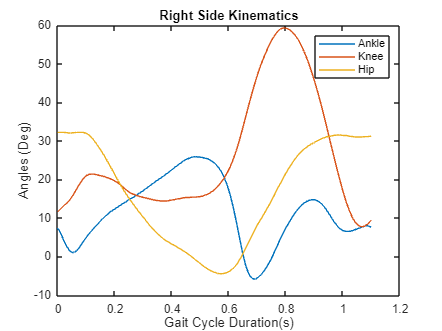

t = linspace(0,sub.gaitCycleDuration,101);
plot(t,cell2num(sub.rightSide));
xlabel('Gait Cycle Duration(s)');
ylabel('Angles (Deg)');
title('Right Side Kinematics');
legend('Ankle','Knee','Hip');

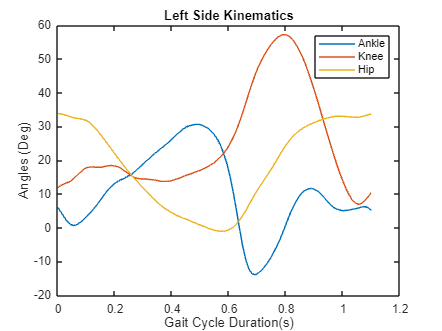


figure;
plot(t,cell2num(sub.leftSide));
xlabel('Gait Cycle Duration(s)');
ylabel('Angles (Deg)');
title('Left Side Kinematics');
legend('Ankle','Knee','Hip');

## Export Data Per Joint

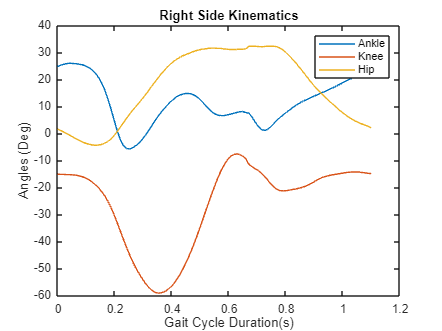

%Have to create phase shift between right and left side, used 600 for
%~60%,
%ankle
lAnklePose = cell2num(sub.leftSide(:,1));
rAnklePose = circshift(cell2num(sub.rightSide(:,1)),61);
%knee
lKneePose = -cell2num(sub.leftSide(:,2));
rKneePose = -circshift(cell2num(sub.rightSide(:,2)),61);
%hip
lHipPose = cell2num(sub.leftSide(:,3));
rHipPose = circshift(cell2num(sub.rightSide(:,3)),61);

%time diff for derivatives and samples
dt = t(2)-t(1);

% 1st derivatives
%ankle
lAnkleVel = (lAnklePose(2:end) - lAnklePose(1:end-1))./dt;
rAnkleVel = (rAnklePose(2:end) - rAnklePose(1:end-1))./dt;
%knee
lKneeVel = (lKneePose(2:end) - lKneePose(1:end-1))./dt;
rKneeVel = (rKneePose(2:end) - rKneePose(1:end-1))./dt;
%hip
lHipVel = (lHipPose(2:end) - lHipPose(1:end-1))./dt;
rHipVel = (rHipPose(2:end) - rHipPose(1:end-1))./dt;

plot(t,[rAnklePose rKneePose rHipPose]);
xlabel('Gait Cycle Duration(s)');
ylabel('Angles (Deg)');
title('Right Side Kinematics');
legend('Ankle','Knee','Hip');

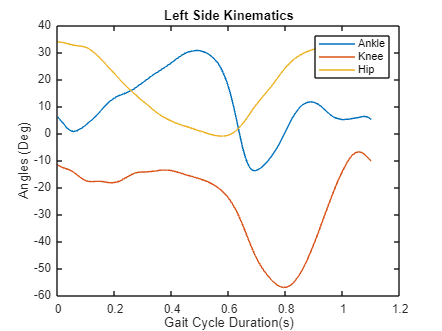


figure;
plot(t,[lAnklePose lKneePose lHipPose]);
xlabel('Gait Cycle Duration(s)');
ylabel('Angles (Deg)');
title('Left Side Kinematics');
legend('Ankle','Knee','Hip');

# NSF5 Model Set Up Variables

%Body
L = sub.Height; %(31.4e-2)/(0.530-0.285); %Length of subject femur 31.4 cm Segment is (0.53H - 0.285H)
M = sub.Mass;
d = .005;

%Hat
hatLength = (0.818-0.530)*L;
hatMass = 0.678*M;
hatCoG = 0.5*hatLength - 0.626*hatLength;
hatRoG = 0.496*hatLength;
hatInertia = hatMass*hatRoG^2;

%Thigh
thighLength = (0.530-0.285)*L;
thighMass = 0.100*M;
thighCoG = 0.5*thighLength - 0.433*thighLength;
thighRoG = 0.323*thighLength;
thighInertia = thighMass*thighRoG^2;

%Shank/leg
shankLength = (0.285-0.039)*L;
shankMass = 0.0465*M;
shankCoG = 0.5*shankLength - 0.433*shankLength;
shankRoG = 0.302*shankLength;
shankInertia = shankMass*shankRoG^2;

%Foot
footHeight = 0.039*L;
footLength = 0.152*L;
footMass = 0.0145*M;
footCoG_x = 0.0304*L;
footCoG_y = 0.0195*L;
footRoG = 0.475*footHeight;
footInertia = footMass*footRoG^2;

%hip natural height
floor = 0.530*L;
%floor spring damper specs
k_floor = 2.646944052407765e+03;%1.5e4/4;
c_floor = 62.818842931179454;%1500/2;

tf = t(end);


## Get the initial position

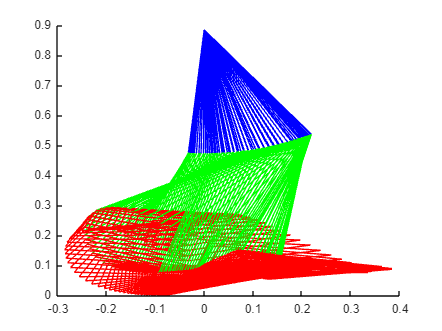

%Poses
x_knee = thighLength * sind(rHipPose);
y_knee = -thighLength * cosd(rHipPose);
x_ankle= x_knee + shankLength * sind(rKneePose);
y_ankle= y_knee - shankLength * cosd(rKneePose);
x_foot= x_ankle + footHeight * sind(rAnklePose);
y_foot= y_ankle - footHeight * cosd(rAnklePose);
x_toes= x_foot + (footLength-.0204*L) *sind(90 - rAnklePose);
y_toes= y_foot + (footLength-.0204*L) *cosd(90 - rAnklePose);
x_heel= x_foot - .0204*L *sind(90 - rAnklePose);
y_heel= y_foot - .0204*L *cosd(90 - rAnklePose);

%initial position

initialOffset = min(y_heel(:,1));

x_hip = zeros([101,1]);
y_hip = zeros([101,1]) - initialOffset;
y_knee = y_knee - initialOffset;
y_ankle= y_ankle - initialOffset;
y_foot= y_foot - initialOffset;
y_toes= y_toes - initialOffset;
y_heel= y_heel - initialOffset;

figure;
hold on;
yline(0,'k');

for i = 1:length(x_hip)
    plot([x_hip(i,1),x_knee(i,1)],[y_hip(i,1),y_knee(i,1)],'b');
    plot([x_knee(i,1),x_ankle(i,1)],[y_knee(i,1),y_ankle(i,1)],'g');
    plot([x_ankle(i,1),x_toes(i,1)],[y_ankle(i,1),y_toes(i,1)],'r');
    plot([x_ankle(i,1),x_heel(i,1)],[y_ankle(i,1),y_heel(i,1)],'r');
    plot([x_heel(i,1),x_toes(i,1)],[y_heel(i,1),y_toes(i,1)],'r');
    % plot([x_ankle(i),x_foot(i)],[y_ankle(i),y_foot(i)],'r');
    % plot([x_foot(i),x_toes(i)],[y_foot(i),y_toes(i)],'r');
    % plot([x_heel(i),x_foot(i)],[y_heel(i),y_foot(i)],'r');
    drawnow; %pause(.001);
    %axis([-0.5 0.5 -0.1 1]);
end

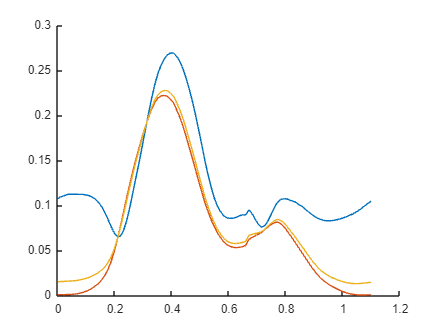


figure; hold on;
plot(t,y_toes(:));
plot(t,y_heel(:));
plot(t,y_foot(:));